# Pendulum exercise

Initialization part

clear all
close all
clc

% Initialize simulation variables
theta_setpoint = 1;  % [rad] set-point for the pendulum angular position
debug_mode = 0;      % debug mode flag (1=debug, 0=normal)

% Desired closed-loop response characteristics
T_settle = 2;    %   [s] settling time
settling_perc = 5;     % desired percentage of the set-point for the settling time
xi = 0.6;     % desired closed-loop damping
omega_c = -log(0.01*settling_perc)/(T_settle*xi);   % [rad/s] desired closed-loop bandwidth


% Simulation settings
Tsim = 10;
rel_tol= 1e-6;

% Initialize pendulum variables
M = 0.5;    % [kg] mass of the pendulum tip
l = 0.3;    % [m] length of the pendulum rod
c = 0.1;    % viscous friction coefficient
g = 9.81;    % [m/s^2] acceleration due to gravity

% Sensor noise
pow = 0;
Ts = 1e-3;

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Manual control settings
u_manual = 0;   % [Nm] manual control action (motor torque)
manual_control_flag = 1;    % flag to switch from manual to adrc control (1=manual, 0=adrc)

% ADRC controller setup
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
omega_o = 10*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];
L = [ l1 ;
      l2 ;
      l3 ];

First we perform a debug to be sure that we have implemented correctly the ESO and the state-feedback controller

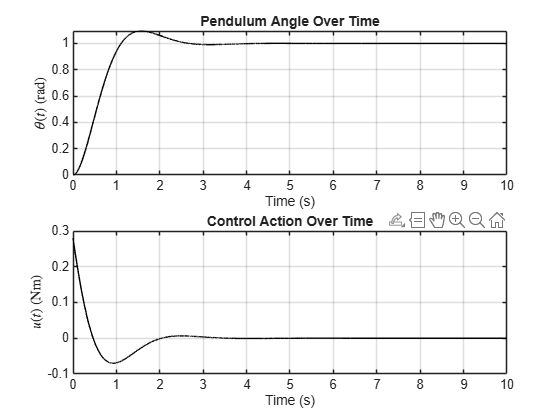

debug_mode = 1;      % debug mode flag (1=debug, 0=normal)

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('Time (s)');
ylabel('$u (t)$ (Nm)','Interpreter','latex');
title('Control Action Over Time');
grid on;

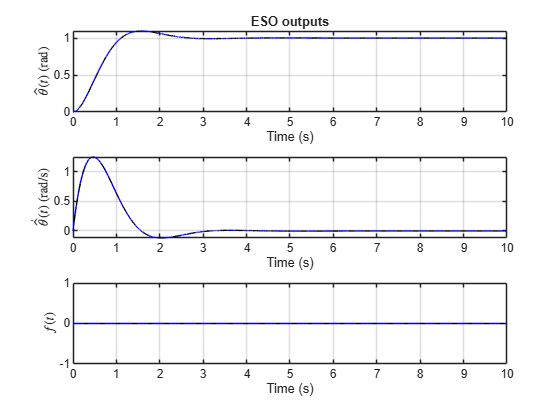


figure;
subplot(3,1,1)
plot(t, theta, 'k');
hold on 
plot(t, theta_hat, '--b');
xlabel('Time (s)');
ylabel('$\hat{\theta} (t)$ (rad)','Interpreter','latex');
grid on
title('ESO outputs');
subplot(3,1,2)
plot(t, theta_dot, 'k');
hold on 
plot(t, theta_hat_dot, '--b');
xlabel('Time (s)');
ylabel('$\dot{\hat{\theta}} (t)$ (rad/s)','Interpreter','latex');
grid on;
subplot(3,1,3)
plot(t, f, 'k');
hold on 
plot(t, f_hat, '--b');
grid on
xlabel('Time (s)');
ylabel('$f(t)$','Interpreter','latex');

Perform a simulation from initial conditions and plot the results

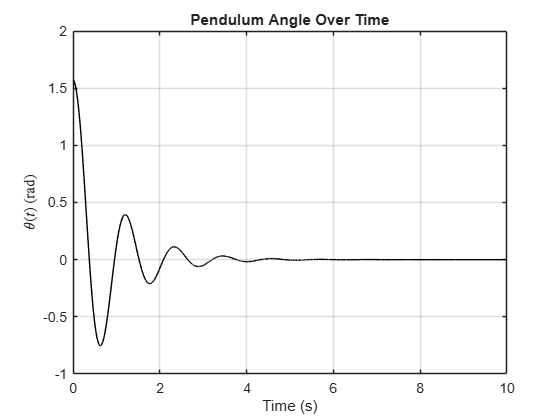

debug_mode = 0;      % debug mode flag (1=debug, 0=normal)
manual_control_flag = 1; % flag to switch from manual to adrc control (1=manual, 0=adrc)

theta_init = pi/2; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;

% Plot the results of the simulation
figure;
plot(t, theta, 'k');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;

Then, to check that the pendulum model is correct we give as input the torque necessary to keep the pendulum steady in the initial conditions and we check the results.

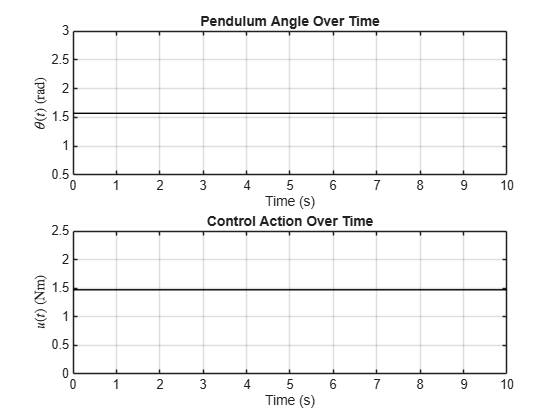

u_manual = M*g*l;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('Time (s)');
ylabel('$u (t)$ (Nm)','Interpreter','latex');
title('Control Action Over Time');
grid on;

Then, we initialize the pendulum to its equilibrium position end we check the effect of applying a motor torque.

We also check the behavior of the ESO.

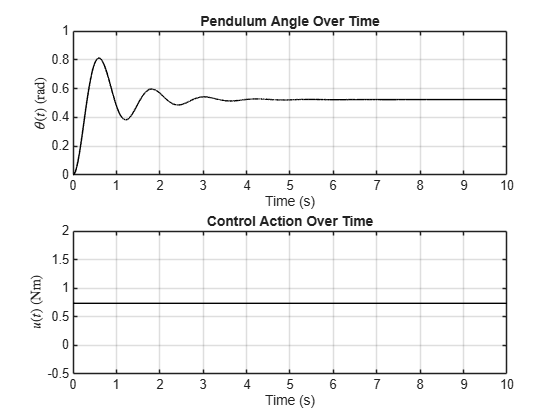

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

u_manual = (M*g*l)/2;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('Time (s)');
ylabel('$u (t)$ (Nm)','Interpreter','latex');
title('Control Action Over Time');
grid on;

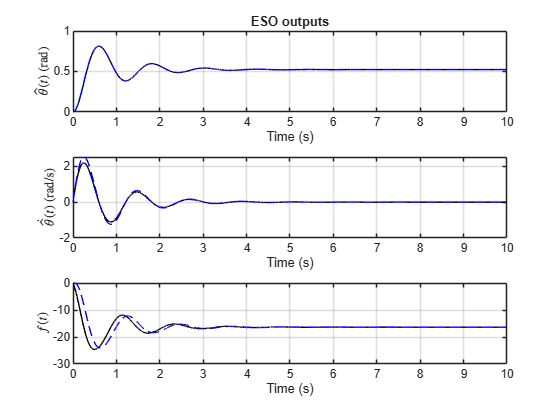

figure;
subplot(3,1,1)
plot(t, theta, 'k');
hold on 
plot(t, theta_hat, '--b');
xlabel('Time (s)');
ylabel('$\hat{\theta} (t)$ (rad)','Interpreter','latex');
grid on
title('ESO outputs');
subplot(3,1,2)
plot(t, theta_dot, 'k');
hold on 
plot(t, theta_hat_dot, '--b');
xlabel('Time (s)');
ylabel('$\dot{\hat{\theta}} (t)$ (rad/s)','Interpreter','latex');
grid on;
subplot(3,1,3)
plot(t, f, 'k');
hold on 
plot(t, f_hat, '--b');
grid on
xlabel('Time (s)');
ylabel('$f(t)$','Interpreter','latex');

Now we perform a closed-loop simulation by enabling the ADRC controller and we check if the control specifications are met

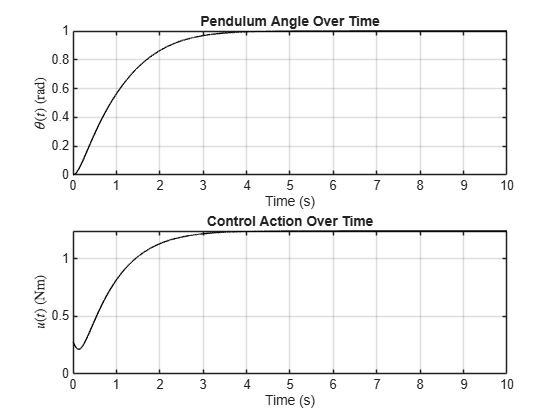

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('Time (s)');
ylabel('$\theta (t)$ (rad)','Interpreter','latex');
title('Pendulum Angle Over Time');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('Time (s)');
ylabel('$u (t)$ (Nm)','Interpreter','latex');
title('Control Action Over Time');
grid on;

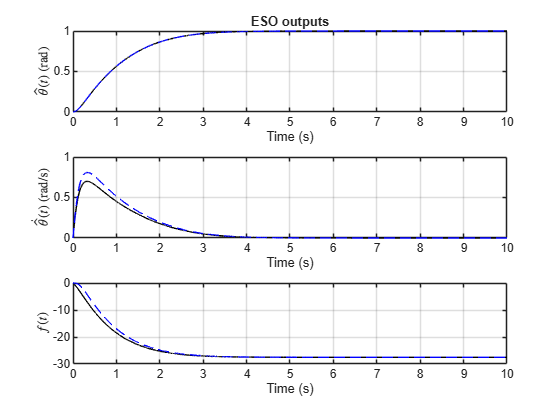


figure;
subplot(3,1,1)
plot(t, theta, 'k');
hold on 
plot(t, theta_hat, '--b');
xlabel('Time (s)');
ylabel('$\hat{\theta} (t)$ (rad)','Interpreter','latex');
grid on
title('ESO outputs');
subplot(3,1,2)
plot(t, theta_dot, 'k');
hold on 
plot(t, theta_hat_dot, '--b');
xlabel('Time (s)');
ylabel('$\dot{\hat{\theta}} (t)$ (rad/s)','Interpreter','latex');
grid on;
subplot(3,1,3)
plot(t, f, 'k');
hold on 
plot(t, f_hat, '--b');
grid on
xlabel('Time (s)');
ylabel('$f(t)$','Interpreter','latex');

Now we consider measurement noise.

% Sensor noise
pow = 1e-6;